### Spatial and Temporal Plots for $\epsilon$

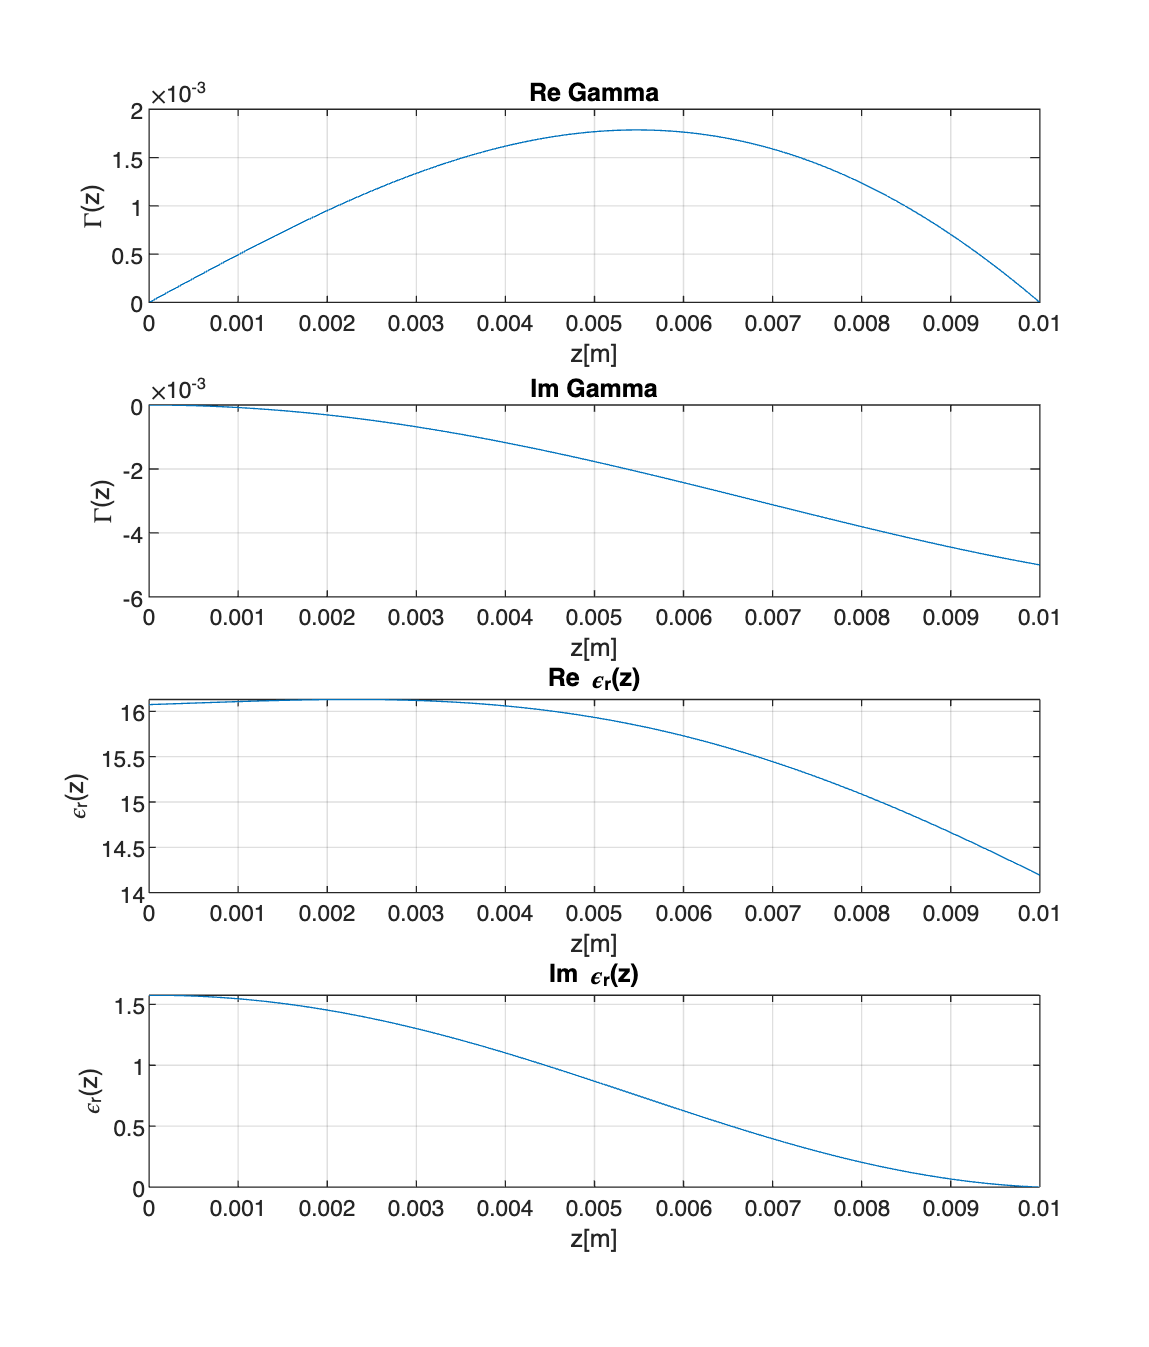

% Spacial variations

L = 0.01;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 1e2;
vp = 4e8;
z = linspace(0, L, N_L);

E = omega/vp;
Gamma = 0.5*z.*exp(-E.*1j.*z);
dGamma = 0.5*(-1j.*E)*z.*exp(-E.*1j.*z) + 0.5*exp(-E.*1j.*z);

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);

figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(4,1,1)
plot(z, real(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Re Gamma")

subplot(4,1,2)
plot(z, imag(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Im Gamma")

subplot(4,1,3)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(4,1,4)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

Temporal change

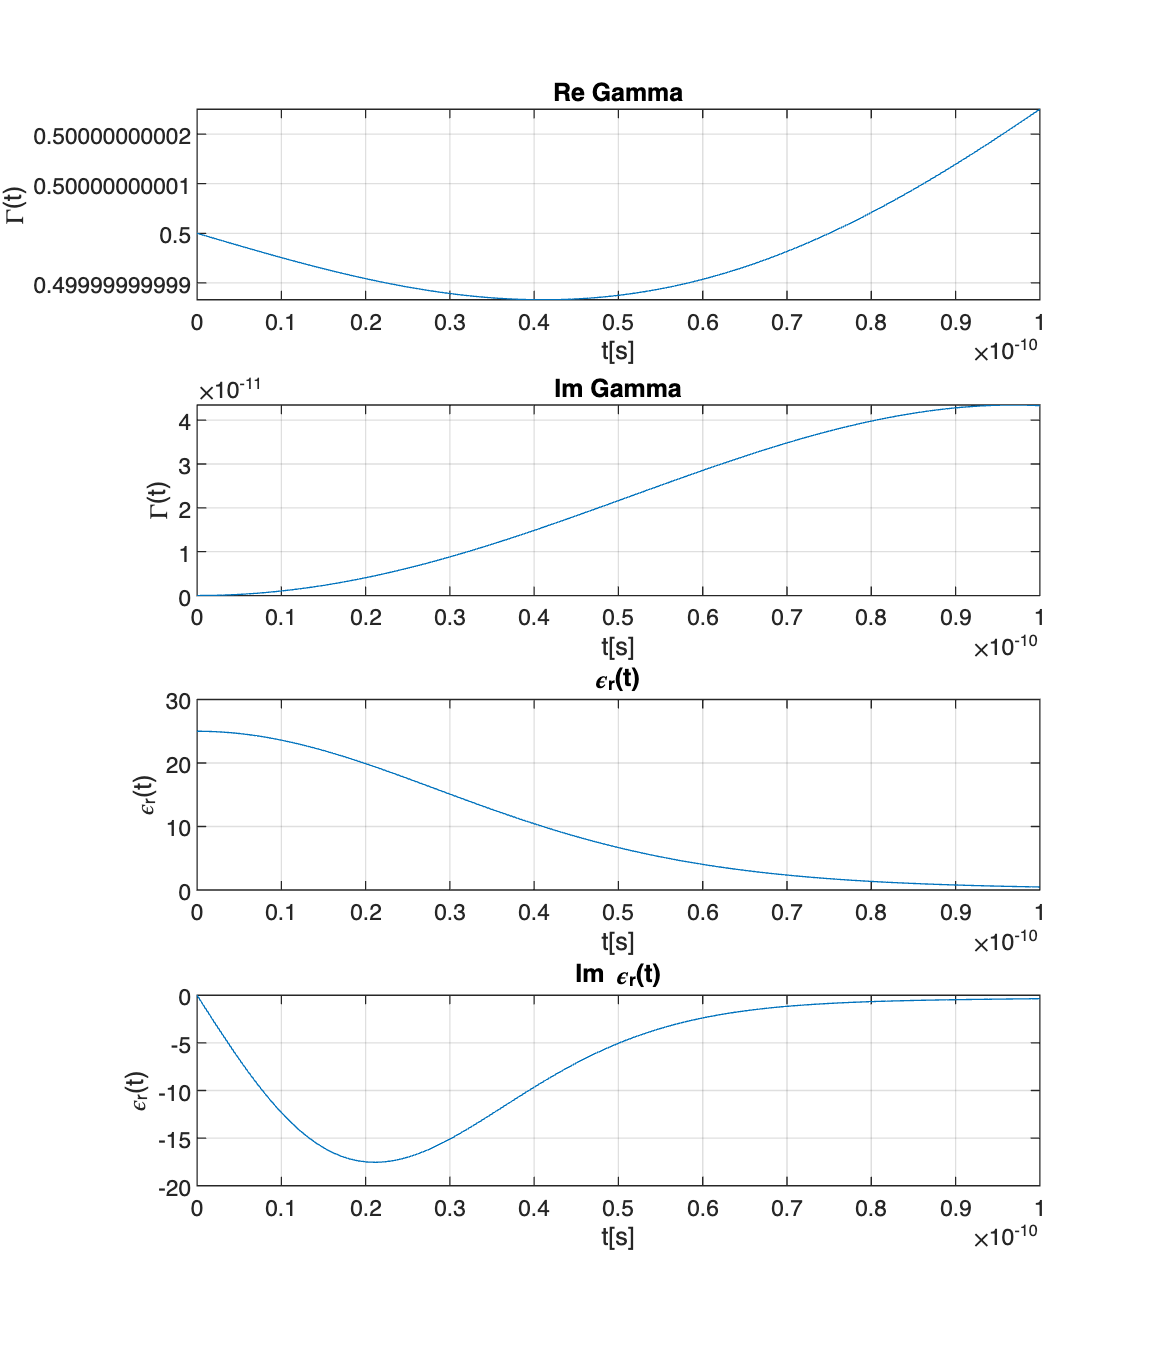

clear Gamma dGamma
T = 1e-10;
N_T = 100;
t = linspace(0, T, N_T);

F = omega/3;

Gamma = 0.5-0.5*t.*exp(-F.*1j.*t);
dGamma = -0.5*exp(-F.*1j.*t) - 0.5*(-F.*1j)*exp(-F.*1j.*t);

a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) + I.^(-1).*D ).^(-2);

figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(4,1,1)
plot(t, real(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Re Gamma")

subplot(4,1,2)
plot(t, imag(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Im Gamma")

subplot(4,1,3)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")
subplot(4,1,4)
plot(t, imag(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Im \epsilon_r(t)")

### Relating with $L$ and $C$